### Inizializzazione

[olive, text]=xlsread('dataset');
obj_lab=text(2:383,1);
var_lab=text(1,2:end);
for i=1:7 
    olive_lab{i}=deblank(var_lab{i}); 
end
grp = categorical(strtrim(string(obj_lab)));

### Line plot (parralel coordinates)

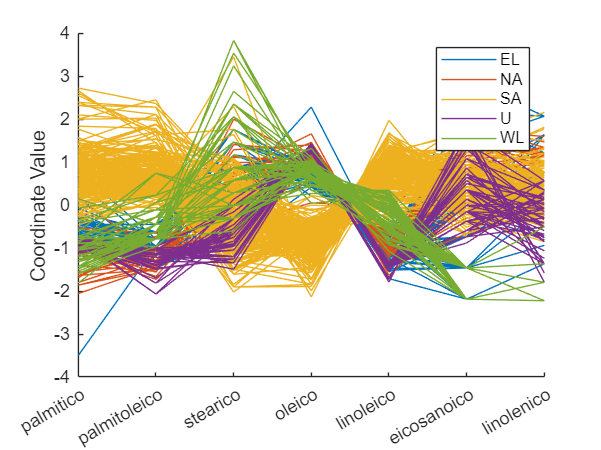

figure;
parallelcoords(olive,'group',grp,'labels',olive_lab,'standardize','on');

### Gplotmatrix

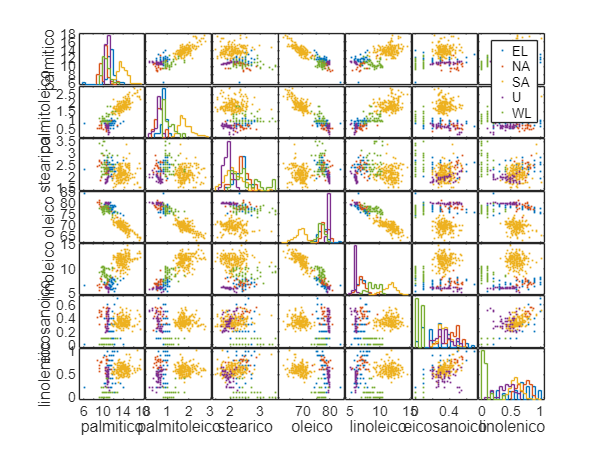

figure;
gplotmatrix(olive,[],grp,[],[],[],[],'stairs',olive_lab,olive_lab);

### Scatter hist ripetto alle variabili Linoleico e Oleico

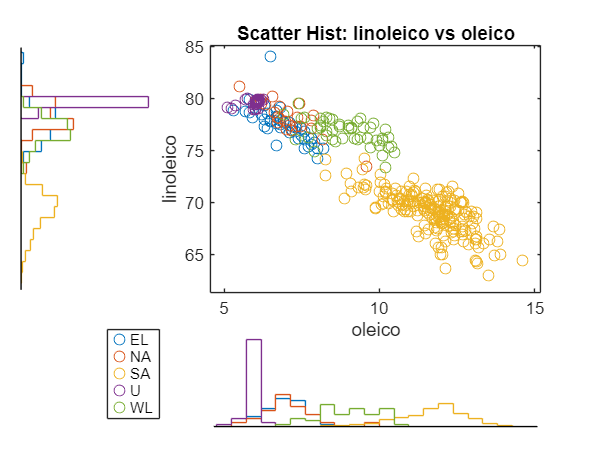

figure;
linoleico = olive(:,4);
oleico = olive(:,5);
scatterhist(oleico,linoleico,'Group',grp);
xlabel(olive_lab{4});
ylabel(olive_lab{5});
title(['Scatter Hist: ' olive_lab{5} ' vs ' olive_lab{4}]);

legend('show');

### Istogrammi di frequenza per ciascuna variabile

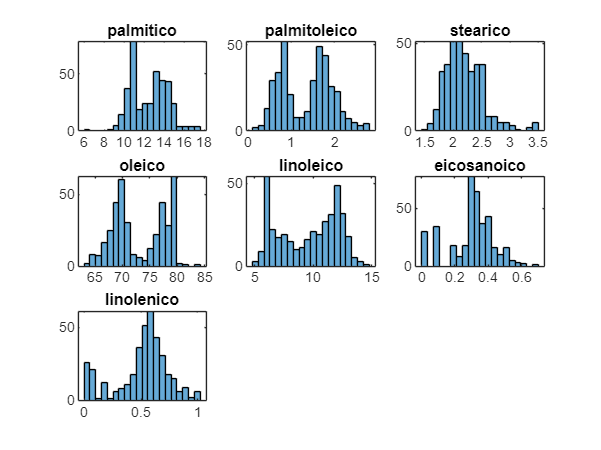

figure;
[n,m] = size(olive);
nbin = ceil(sqrt(n));
msp = ceil(sqrt(m));
for i = 1:m
    hold on;
    subplot(msp, msp, i);
    histogram(olive(:,i), nbin);
    title(olive_lab{i});
end

### Boxplot distinti per ciascuna variabile evidenziando le categorie

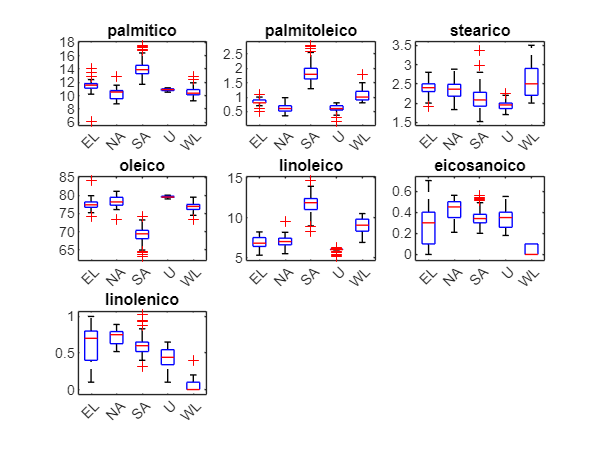

figure;
[n,m] = size(olive_lab);
msp = ceil(sqrt(m));
for i = 1:m
    subplot(msp, msp, i);
    boxplot(olive(:,i), grp);
    title(olive_lab{i});
end

### Imagesc dati tal quali e dati standardizzati

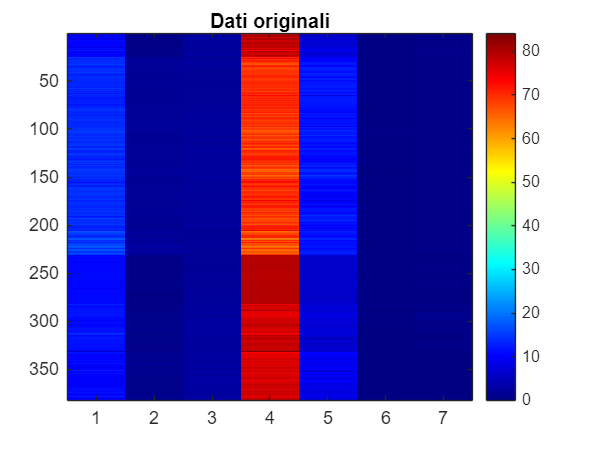

figure;
imagesc(olive);
colormap('jet');
colorbar;
title('Dati originali');

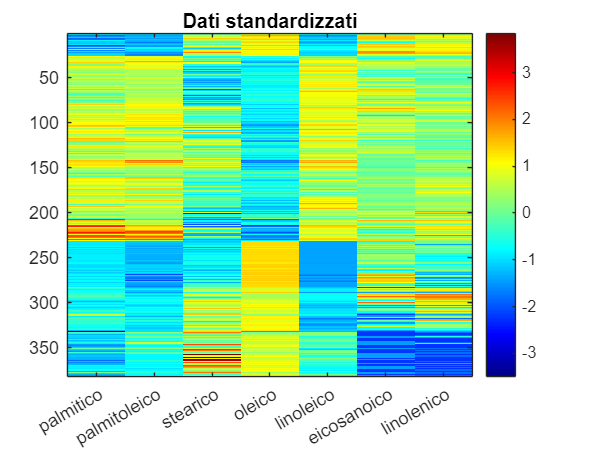


figure;
imagesc(normalize(olive, 'zscore'));
colormap('jet');
colorbar;
ax = gca;
set(ax, 'XTickMode', 'manual');
set(ax, 'XTick', 1:length(olive_lab));
set(ax, 'XTickLabel', olive_lab);
title('Dati standardizzati');

### Matrice di correlazione al quadrato

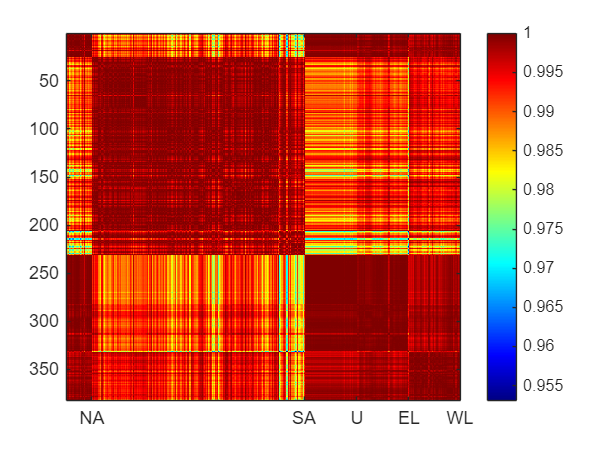

figure;
imagesc(corrcoef(olive').^2);
colormap('jet');
colorbar;
ax=gca;
set(ax,'XTickmode','manual');
cat=unique(grp,'stable');
for i=1:numel(cat) 
    ic(i) = nnz(grp == cat(i));
end
set(ax,'XTick',cumsum(ic));
set(ax,'XTickLabel',cat);